clc;
clear all;
format long;

**QUESTION 1**

tol = 1e-10;
N = 200;
A = 2*eye(N) + 0.5*randn(N)/sqrt(N);
b=ones(N,1);

[x,count,res] = gmres(A,b,tol);

Number_of_iterations = count

Number_of_iterations =     17


Relative_residual = res

Relative_residual =      2.651599975774699e-11


x

x =    0.417388678382920
   0.444116244321480
   0.603989220402142
   0.624358966508581
   0.571960247451142
   0.615319684829854
   0.457736678945849
   0.471029674248211
   0.533781752269781
   0.487029811104033


**QUESTION 2**

%%% 2b %%%%%%

q = @(z) (1/16)*(231*z.^6 - 315*z.^4 + 105*z.^2 -5);

p = @(z)(16/231)*q(z)

p = function_handle with value:
    @(z)(16/231)*q(z)


syms z
X = companion_matrix(p(z))

X =                    0   1.000000000000000                   0                   0                   0                   0
                   0                   0   1.000000000000000                   0                   0                   0
                   0                   0                   0   1.000000000000000                   0                   0
                   0                   0                   0                   0   1.000000000000000                   0
                   0                   0                   0                   0                   0   1.000000000000000
   0.021645021645022                   0  -0.454545454545455                   0   1.363636363636364                   0


eiggs = eig(X)

eiggs =   -0.932469514203151
  -0.661209386466264
   0.932469514203153
   0.661209386466265
  -0.238619186083197
   0.238619186083197


%% sorted roots
sort(eiggs)

ans =   -0.932469514203151
  -0.661209386466264
  -0.238619186083197
   0.238619186083197
   0.661209386466265
   0.932469514203153


q(eiggs) % Verify that they are actual roots

ans = 1.0e-13 *

  -0.106581410364015
   0.008881784197001
   0.044408920985006
  -0.004440892098501
  -0.006106226635438
  -0.003885780586188


**QUESTION 3**

%%% 3a %%%%%%%%

%%% 3b %%%%%%%%

%rqi(A,x0,ep)
N = 6;
a1 = -2*ones(N,1);
a2 = ones(N-1,1);
A = diag(a2,-1)+diag(a1)+diag(a2,1);
x0 =  (1/sqrt(6)).*ones(N,1);

ep = 1e-10;
[v,lam,iteration_count] = rqi(A,x0,ep)

v =    0.231939176669697
   0.417913061018633
   0.521107370659655
   0.521107370659655
   0.417913061018633
   0.231939176669697


lam =   -0.198062265752671


iteration_count =      3


% verify results

[vn,d] = eig(A)

vn =    0.231920613924330  -0.417906505941275  -0.521120889169602   0.521120889169603  -0.417906505941275  -0.231920613924330
  -0.417906505941275   0.521120889169603   0.231920613924330   0.231920613924330  -0.521120889169602  -0.417906505941275
   0.521120889169603  -0.231920613924330   0.417906505941275  -0.417906505941275  -0.231920613924330  -0.521120889169602
  -0.521120889169603  -0.231920613924330  -0.417906505941275  -0.417906505941275   0.231920613924330  -0.521120889169602
   0.417906505941275   0.521120889169602  -0.231920613924330   0.231920613924330   0.521120889169602  -0.417906505941275
  -0.231920613924330  -0.417906505941275   0.521120889169602   0.521120889169602   0.417906505941275  -0.231920613924330


d =   -3.801937735804839                   0                   0                   0                   0                   0
                   0  -3.246979603717467                   0                   0                   0                   0
                   0                   0  -2.445041867912629                   0                   0                   0
                   0                   0                   0  -1.554958132087371                   0                   0
                   0                   0                   0                   0  -0.753020396282533                   0
                   0                   0                   0                   0                   0  -0.198062264195162


lam_err = abs(d(end,end) - lam)

lam_err =      1.557509121674627e-09


v_error = abs(vn(:,end)-(-v))

v_error = 1.0e-04 *

   0.185627453672121
   0.065550773586942
   0.135185099473523
   0.135185099472412
   0.065550773586942
   0.185627453672399


**QUESTION 4**

% set up matrix

A = [3 -1 -1 1;
    -1 2 -1/4 1 ;
    -1 -1 -3 1/2;
    -1/2 -1/4 0 -7];

%centre
c1 = A(1,1);
c2 = A(2,2);
c3 = A(3,3);
c4 = A(4,4);

%radius
r1 = 1 + 1+ 1; r2 = 1 + 1/4 +1;
r3 = 1 +1 + 1/2; r4 = 1/2 +1/4;

true_eigen_values = eig(A)

true_eigen_values =    3.645698826149831
   1.533195532698929
  -3.279302662649521
  -6.899591696199242


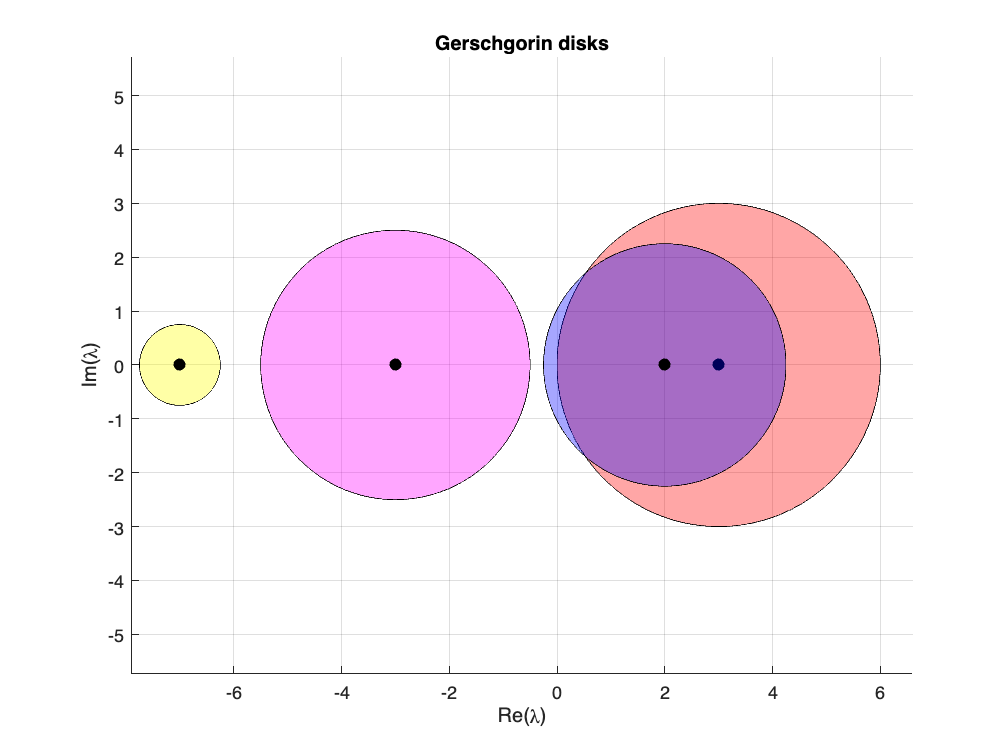

close all;


figure(1)
p = nsidedpoly(1000, 'Center', [c1 0], 'Radius', r1);
plot(p, 'FaceColor', 'r')
axis equal
grid on
hold on
plot(c1,0,'k.','MarkerSize',20)
hold on
p2 = nsidedpoly(1000, 'Center', [c2 0], 'Radius', r2);
plot(p2, 'FaceColor', 'b')
axis equal
hold on
plot(c2,0,'k.','MarkerSize',20)
hold on
p3 = nsidedpoly(1000, 'Center', [c3 0], 'Radius', r3);
plot(p3, 'FaceColor', 'm')
axis equal
hold on
plot(c3,0,'k.','MarkerSize',20)
hold on
p4 = nsidedpoly(1000, 'Center', [c4 0], 'Radius', r4);
plot(p4, 'FaceColor', 'y')
axis equal
hold on
plot(c4,0,'k.','MarkerSize',20)
xlabel("Re(\lambda)"); ylabel("Im(\lambda)");
title("Gerschgorin disks")

According to Gerschgorin's theorem, the matrix A has eigenvalues in the union of the Gerschgorin disks $|\lambda - 3 |<3$,  $|\lambda - 2|<2.25
$,  $|\lambda + 3 |<2.5$ and  $|\lambda + 7 |<0.75$. Since $|\lambda - 3 |<3$,  $|\lambda - 2|<2.25
$ are disjoint from the other two, the  Gerschgorin's theorem tells us that two of the eigenvalues must be in the two disk with the remaining two in the union of the other two disks.

**QUESTION 5**

%%% a

%%% b

SA = [4 7 -6 10 9;
    4 -6 4 9 5;
    -2 4 6 10 3;
    -4 6 3 -3 7;
    -1 8 0 6 2];

UA = zeros(5,5); UA(1,1) = 4; UA(2,2) = 1; UA(3,3) = 3; UA(4,4) = 9; UA(5,5) = 10;

SB = [6 6 -1 5;
    8 7 -6 -6;
    -3 3 -5 10;
    -6 -6 -9 -7];

UB = zeros(4,4); UB(1,1) = -7; UB(2,2) = -4; UB(3,3) = -3; UB(4,4) = -5;

C = [-9 10 6 -7;
    -8 -2 -5 3;
    -7 0 -6 5;
    -8 9 0 8;
    -4 -9 -4 5];

x= silvester(SA,SB,UA,UB,C) % solution

x =    7.164257638512401  10.901274644160024  -0.358273182187601   2.112026215055829
   2.277357282833669   2.038219188954689   0.346773493076260  -0.755989882624110
   3.164640265518682   5.588511648918816  -1.286321203219333   2.534960382610655
  -2.473528353258586  -0.290393814006969  -1.064736389326259   2.264702503984480
  -1.340482562043512  -0.388265945321812  -0.949257360228529   1.772782710005899


function [x,count,R_norm] = gmres(A,b,tol)
m = size(A,1);
q = zeros(m,m);
h = zeros(m,m);
norm_b = norm(b);
q(:,1) = b/norm_b;

for n = 1:m
    v = A*q(:,n);
    for j = 1:n
        h(j,n) = q(:,j)'*v;
        v = v - h(j,n)*q(:,j);
    end
    h(n+1,n) = norm(v);
    q(:,n+1) = v/h(n+1,n);
    H = h(1:n+1,1:n);

    bb = norm_b*speye(n+1,1);
    y = H\bb;

    xn = q(:,1:n)*y;

    r = A*xn - b;

    R_norm = norm(r)/norm_b;

    count = n;

    if (norm(r)< norm_b*tol)
        break
    end
end

x = xn;
end


function X = companion_matrix(p)
coeff = coeffs(p,'all');
c = fliplr(coeff);

N =  polynomialDegree(p);
It = eye(N-1,N-1);

X = [zeros(N-1,1),It];
X = [X; -double(c(1:N))];
end


function [v,lam,count] = rqi(A,x0,ep)
N =size(A,2);
v = x0;
I = eye(N);
lam = v'*A*v;
count = 0;
while true
    p = A - lam*I;
    w = p\v;
    v_new = w/norm(w,2);
    lam_new = v_new'*A*v_new;

    nmw = norm(A*v_new - lam_new*v_new);

    count = count + 1;
    if nmw < ep
        break
    end

    v = v_new;
    lam = lam_new;

end
end

function x= silvester(SA,SB,UA,UB,C)

N = size(C,2);
n = size(C,1);

I = diag(diag(ones(n)));

invers_SA = inv(SA);
invers_SB = inv(SB);

xht = zeros(n,N);
for j = 1:N
    A = UA - UB(j,j)*I;
    cht = SA*C*invers_SB(:,j);
    xht(:,j) = A\cht;
end
x = zeros(n,N);
for i = 1:N
    x(:,i) = invers_SA*xht*SB(:,i);
end
end